## Vortex Shedding

POD (Principal Orthogonal Decomposition) trajectories (projections of velocity and pressure data to a linear subspace) of a flow past a cylinder (2D simulations from CFD). Initial conditions are close to the origin, which is unstable and brings these trajectories.

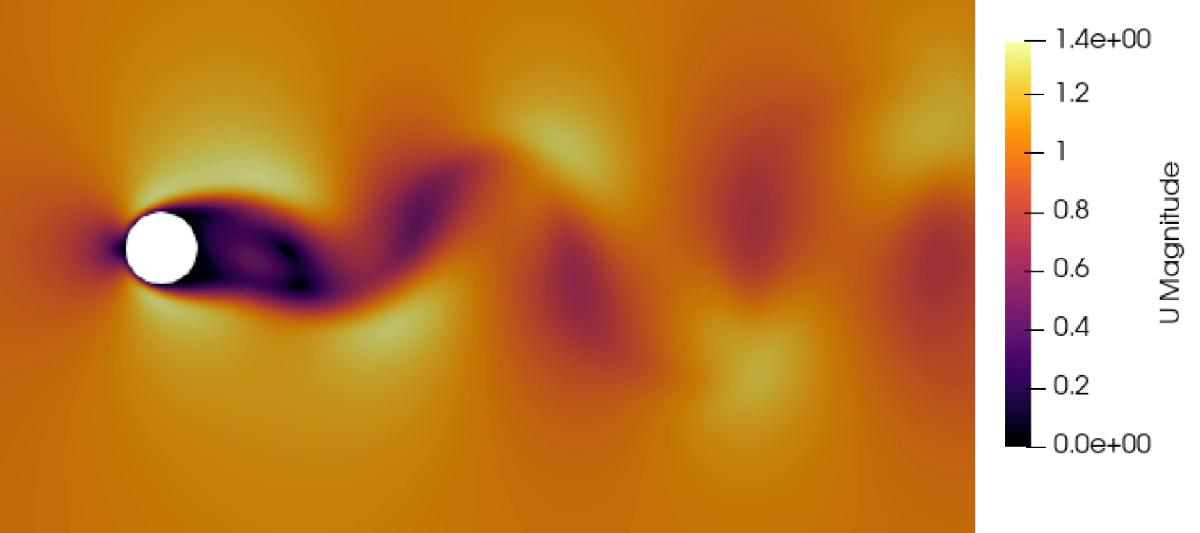 

The first two PODs are the most energetic one and the last one in our set is the so-called shift mode that quantifies the correction from the unstable equilibrium to the mean flow of the limit cycle.

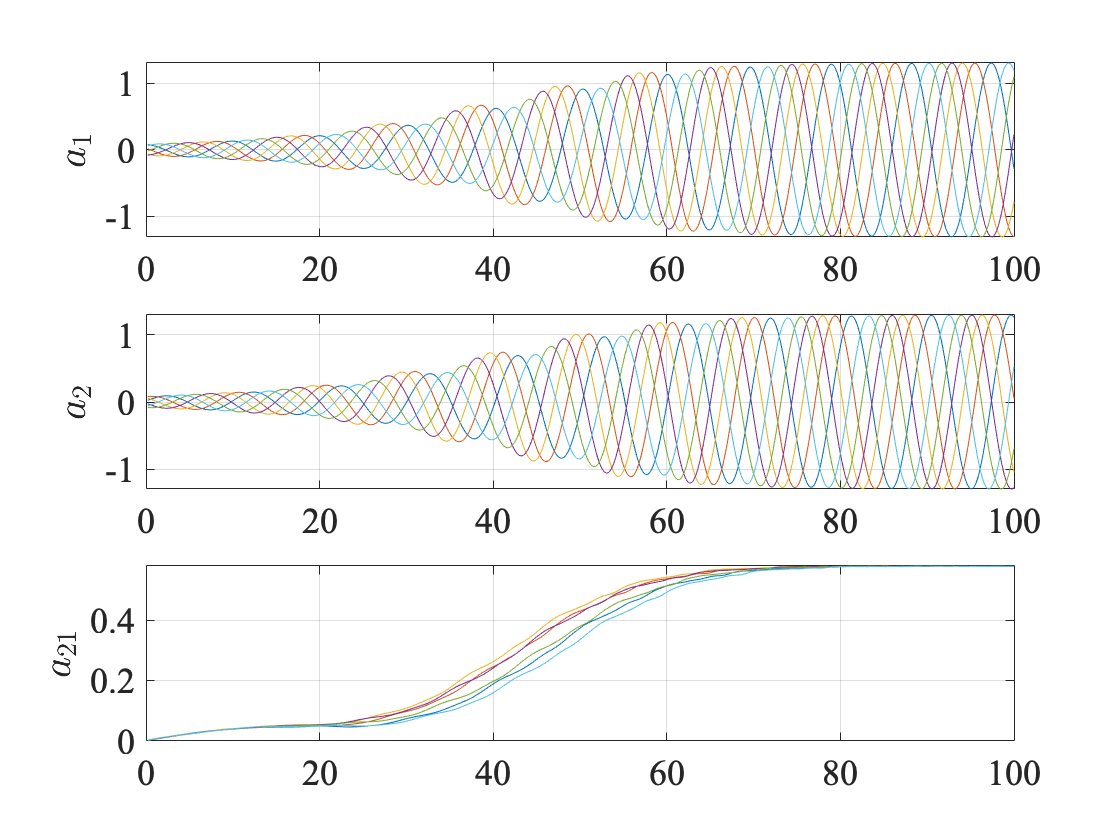

clear all
close all
clc


load data_VortexShedd.mat
idx = [1 2 21];
figure; title('Synthetic Data')
for ii = 1:6
    for jj = 1:3
subplot(3,1,jj); hold on; grid on; box on;
plot(POD_traj{ii,1},POD_traj{ii,2}(idx(jj),:))
zlabel(['$ t$'],'Interpreter','latex')
ylabel(['$a_{' num2str(idx(jj)) '}$'],'Interpreter','latex')
set(gca,'fontname','times')
set(gca,'fontsize',18)
    end
end

## Datadriven SSM

% Data embedding
SSM_dim = 2; 
[X_traj,opts_embd] = coordinates_embedding(POD_traj,SSM_dim);

The embedding coordinates consist of the measured states.


opts_embd

opts_embd = struct with fields:
            IMdimensions: 2
           OverEmbedding: 0
          ForceEmbedding: 0
            TimeStepping: 1
              ShiftSteps: 1
             Observables: 21
    ObservableStateSpace: 'x(t)'



% Split in training and testing dataset
ind_test = [6];
X_train = X_traj;
X_test = X_traj(ind_test,:);
X_train(ind_test,:)=[];

Polynomial degree of the parametrization

ParamDeg = 17; 
% The first two coordinates may be used to parametrizaed the manifold
% (typically done in literature)
%V = [eye(SSM_dim); zeros(size(X_traj{1,2},1)-SSM_dim,SSM_dim)];
[V_ort_data,SSM_func,IM_para_info] = IMparametrization(X_train,SSM_dim,ParamDeg);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    1.195950e-05    9.567e-14    9.103e-08

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<

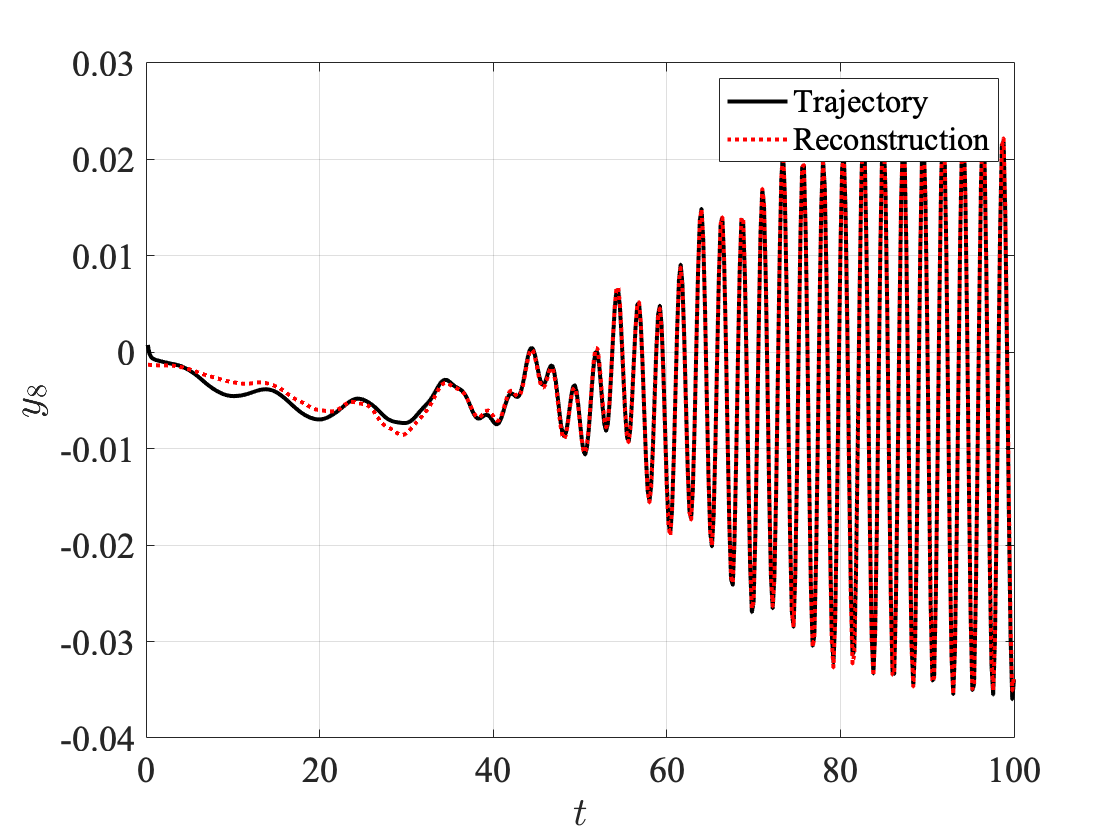


% Plot and validation
figure(2); clf; hold on; grid on; box on; 
figure(3); clf; hold on; grid on; box on; colors = winter(size(X_traj,1) );
options = odeset('RelTol',1e-4,'AbsTol',1e-8);
Err_rec = []; Y = [];
coordplot = 8; coordsplot = [1 2 3];
for ii = 1:size(X_traj,1)
    % Simulate synthetic data, get observables and reconstruct test data
    t = X_traj{ii,1}; x = X_traj{ii,2};
    y = transpose(V_ort_data)*x; Y = [Y y]; x_rec = SSM_func(y);
    % Error evaluation
    Err_rec = [Err_rec; sqrt(sum( (x-x_rec).^2 ))];
    if ii ==ind_test
        figure(7); clf; hold on; grid on; box on;
        plot(t,x(coordplot,:),'k','Linewidth',2,'DisplayName','Trajectory')
        plot(t,x_rec(coordplot,:),'r:','Linewidth',2,'DisplayName','Reconstruction')
        xlabel('$t$','Interpreter','latex')
        ylabel(['$y_{' num2str(coordplot) '}$'],'Interpreter','latex')
        set(gca,'fontname','times')
        set(gca,'fontsize',18)
        legend
    end
    figure(2)
    q1 = x(coordsplot(1),:); q2 = x(coordsplot(2),:); q3 = x(coordsplot(3),:);
    plot3(q1,q2,q3,'Linewidth',2,'Color',colors(ii,:))
    figure(3)
    q1 = y(1,:); q2 = y(2,:);
    plot(q1,q2,'Linewidth',2,'Color',colors(ii,:))
end

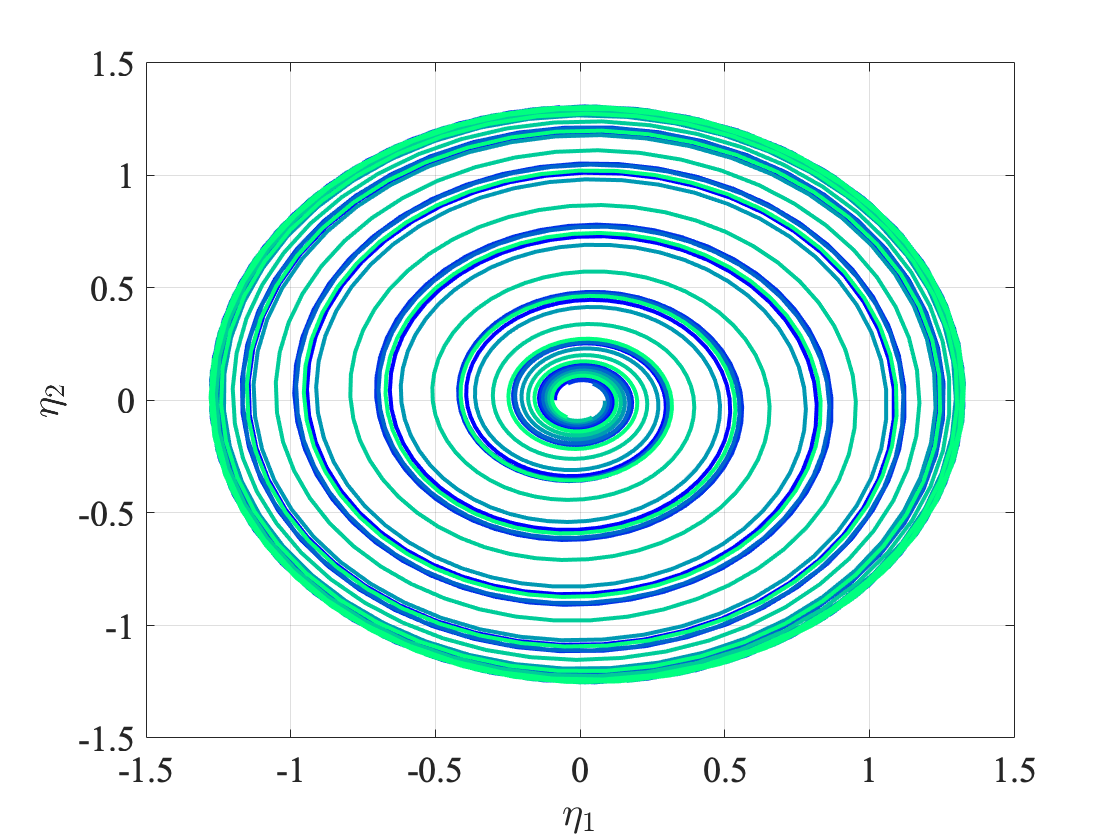

xlabel('$\eta_1$','Interpreter','latex')
ylabel('$\eta_2$','Interpreter','latex')
set(gca,'fontname','times')
set(gca,'fontsize',18)

ARSE = mean(mean(Err_rec))/max(sqrt(sum(x.^2)))*100

ARSE =       0.83281


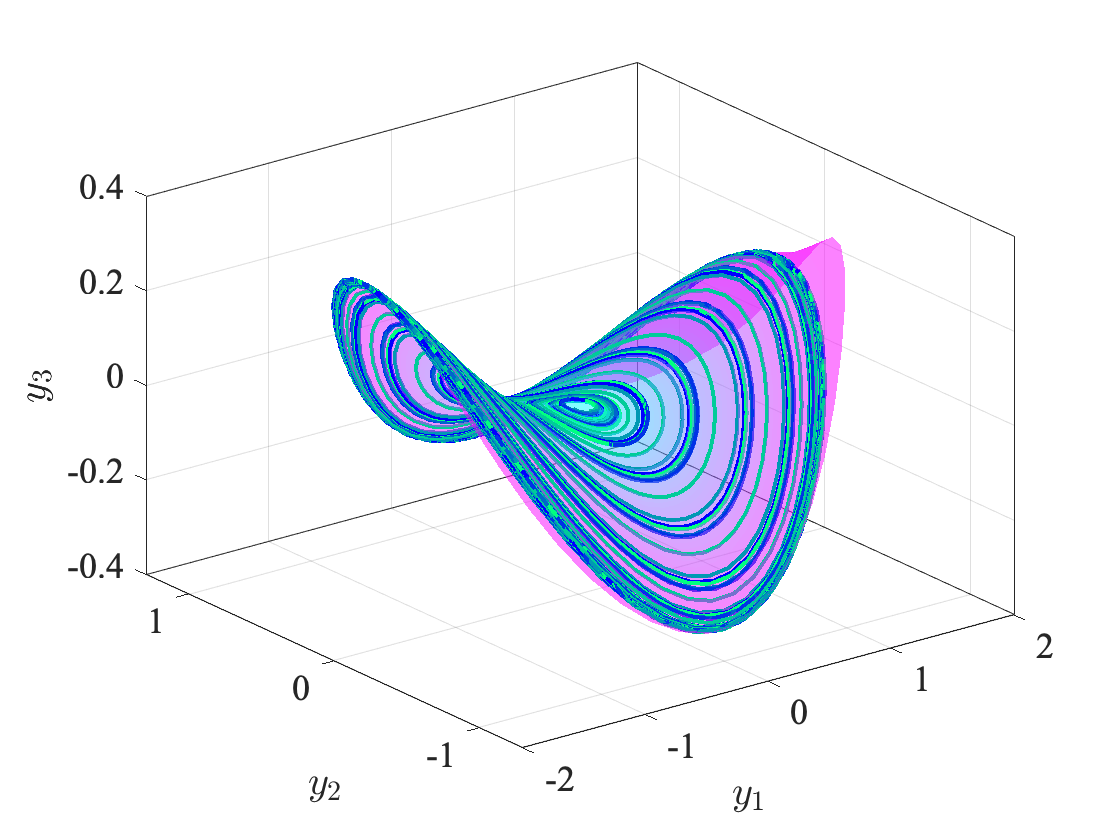


% Plot 3D SSM Surface
figure(2); 
h = plot_2dSSM_surf(coordsplot,Y,SSM_func,1,50,0);
xlabel(['$y_{' num2str(coordsplot(1)) '}$'],'Interpreter','latex')
ylabel(['$y_{' num2str(coordsplot(2)) '}$'],'Interpreter','latex')
zlabel(['$y_{' num2str(coordsplot(3)) '}$'],'Interpreter','latex')
set(gca,'fontname','times')
set(gca,'fontsize',18)

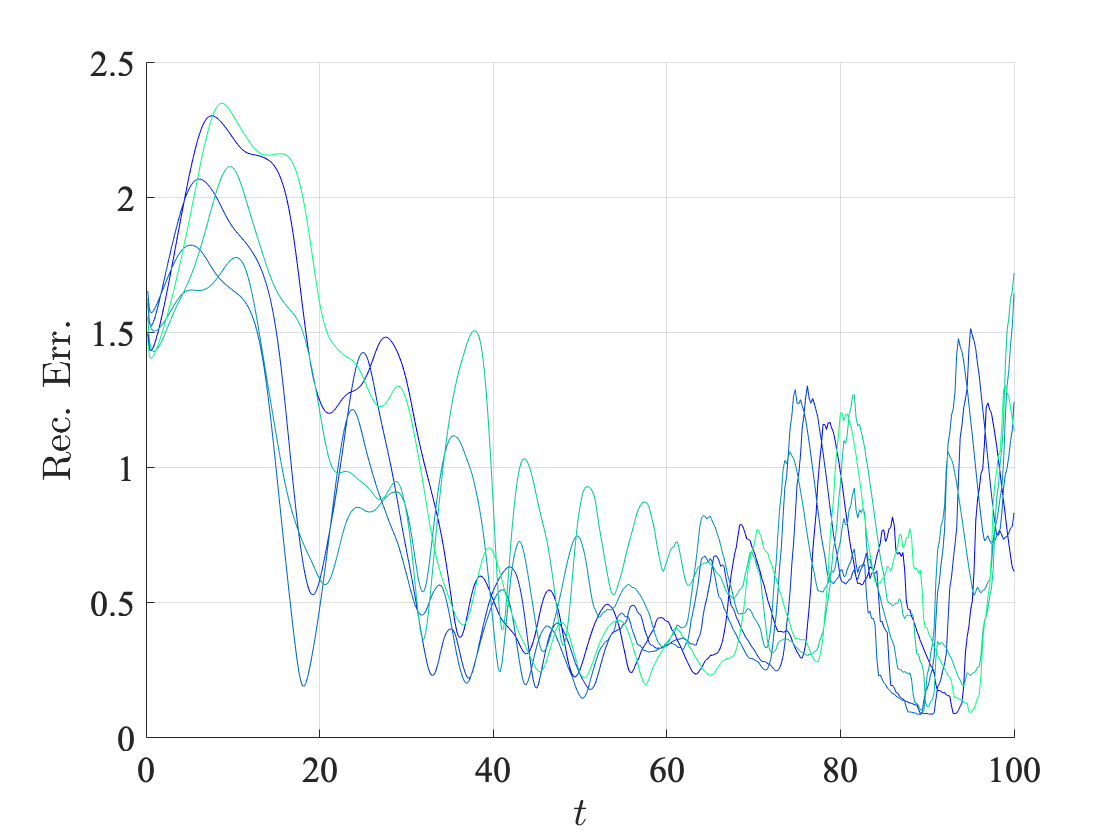


figure; hold on; grid on;  colororder(winter(size(X_traj,1) ));
plot(t,Err_rec(:,:)/max(sqrt(sum(x.^2)))*100)
xlabel('$t$','Interpreter','latex')
ylabel('Rec. Err.','Interpreter','latex')
set(gca,'fontname','times')
set(gca,'fontsize',18)

## Reduced Dynamics

This example is mildly dissipative. The cubic normal form form is already a good approximation for the dynamics. We can enforce this by specifying the orders for each pf the maps R, iT, N and T. The linear dynamics is estimated only with R.

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1         0.418023                          0.51
     1           2        0.0553589              1          0.176  
     2           3       0.00110463              1         0.0209  
     3           4      0.000325595              1        0.00213  
     4           6      0.000262087             10        0.00127  
     5           7      0.000237218              1        0.00131  
     6           8      0.000231041              1       0.000971  
     7           9      0.000223465              1       0.000753  
     8          10      0.000221808              1        0.00054  
     9          11      0.000220406              1       0.000467  
    10          12       0.00021942              1       0.000341  
    11          13

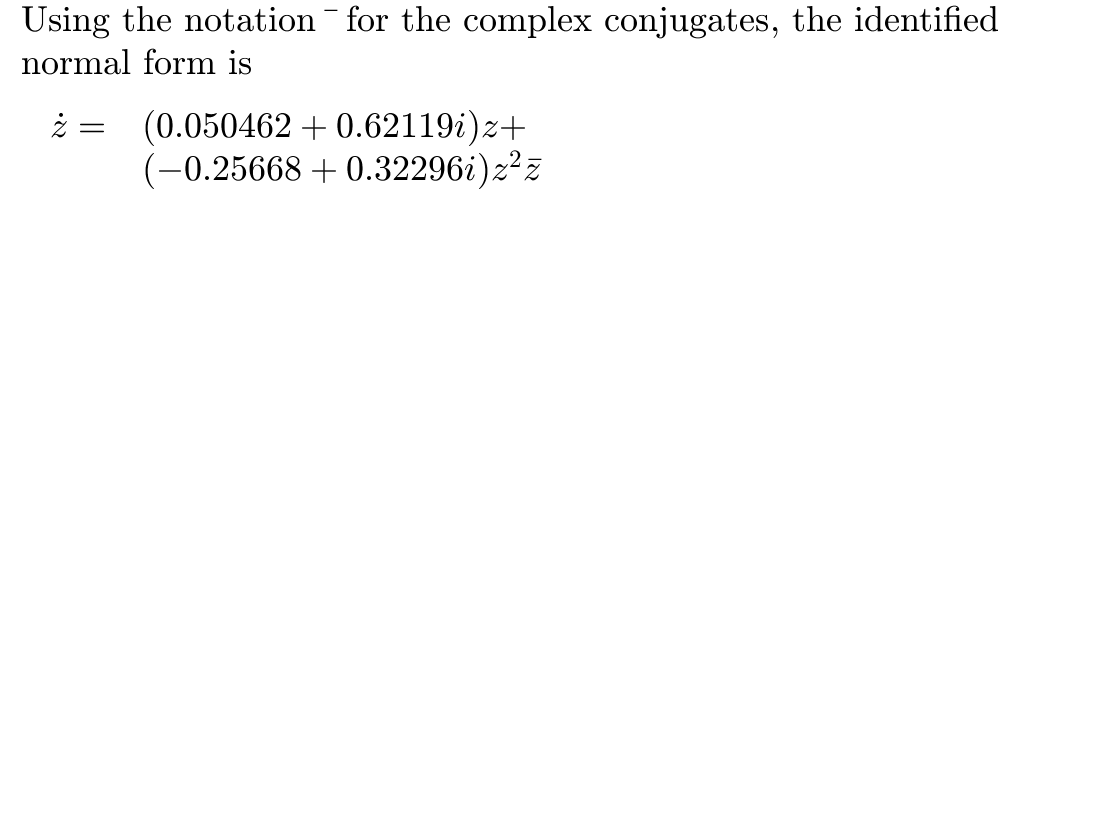

% Arrange trajectories
Y_traj = cell(size(X_traj,1),2);
for ii = 1:size(X_traj,1)
    Y_traj{ii,1} = [X_traj{ii,1}];
    Y_traj{ii,2} = transpose(V_ort_data)*[X_traj{ii,2}];
end
Y_train = Y_traj;
Y_test = Y_traj(ind_test,:);
Y_train(ind_test,:)=[];

% Dynamics identification

flow_map = 1; RPolyOrd = 15; TPolyOrd = 21; NPolyOrd = 3;
[R,iT,N,T,Maps_info] = IMdynamics_flow(Y_train,'R_PolyOrd',RPolyOrd,...
           'N_PolyOrd',NPolyOrd,'T_PolyOrd',TPolyOrd,'style','normalform','MaxIter',3e3);

N_info = Maps_info.N

N_info = struct with fields:
          Map: @(z)cc_transf(W_n*phi_n(z))
        coeff: [0.050462 +    0.62119i -0.25668 +    0.32296i]
          phi: @(y)[y(1:k_red,:);phi_n_nl(y)]
    exponents: [2×2 double]
        LaTeX: '\begin{array}{rl}\dot{z} = &(0.050462+0.62119i) z+ \\ &(-0.25668+0.32296i) z^{2} \bar{z}\end{array}'


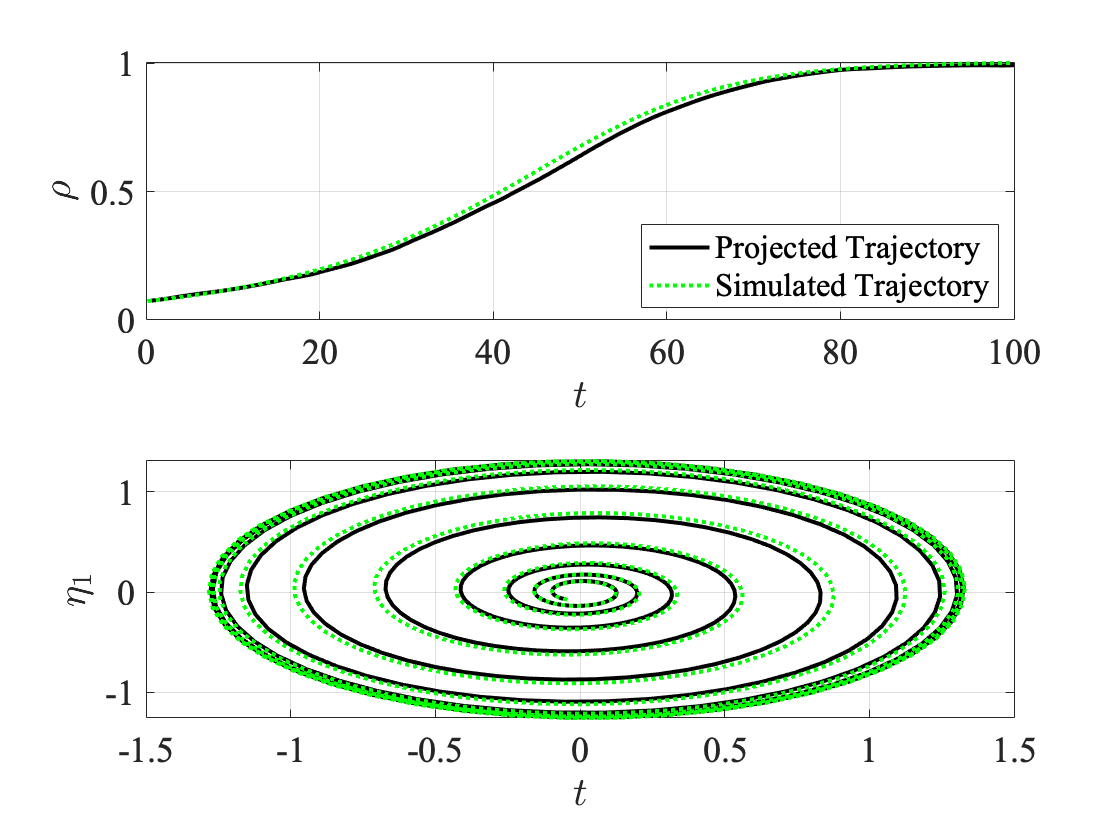

% Evaluation
ii = ind_test;
t_i = Y_traj{ii,1}; y_i = Y_traj{ii,2}; x_i = X_traj{ii,2}; z_i = iT(y_i);
[t_sim,z_sim] = ode45(@(t,x) N(x),t_i,z_i(:,1)); z_sim = transpose(z_sim);

figure(51); clf;
subplot(211); hold on; grid on; box on;
plot(t_i,abs(z_i(1,:))/abs(z_sim(1,end)),'k','Linewidth',2,'DisplayName','Projected Trajectory')
plot(t_sim,abs(z_sim(1,:))/abs(z_sim(1,end)),'g:','Linewidth',2,'DisplayName','Simulated Trajectory')
xlabel('$t$','Interpreter','latex')
ylabel('$\rho$','Interpreter','latex')
set(gca,'fontname','times')
set(gca,'fontsize',18)
legend('location','SE')
y_sim = T(z_sim);
x_sim = SSM_func(y_sim);
subplot(212); hold on; grid on; box on;
plot(y_i(1,:),y_i(2,:),'k','Linewidth',2,'DisplayName','Projected Trajectory')
plot(y_sim(1,:),y_sim(2,:),'g:','Linewidth',2,'DisplayName','Simulated Trajectory')
xlabel('$t$','Interpreter','latex')
ylabel('$\eta_1$','Interpreter','latex')
set(gca,'fontname','times')
set(gca,'fontsize',18)

RMSE = mean(sqrt(sum( (z_i-z_sim).*conj(z_i-z_sim) )))/0.5*100

RMSE =        26.823


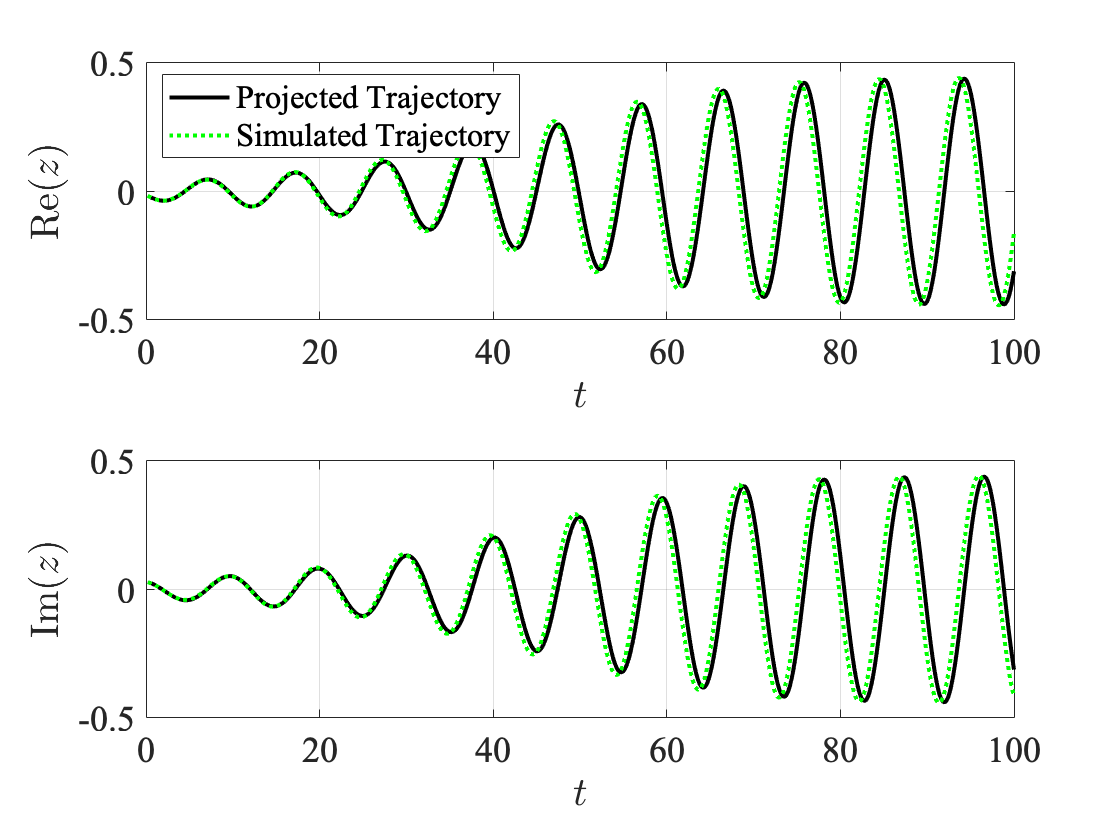


figure(52); clf; Dz = z_i-z_sim;
subplot(211); hold on; grid on; box on;
plot(t_i,real(z_i(1,:)),'k','Linewidth',2,'DisplayName','Projected Trajectory')
plot(t_sim,real(z_sim(1,:)),'g:','Linewidth',2,'DisplayName','Simulated Trajectory')
xlabel('$t$','Interpreter','latex')
ylabel('Re$(z)$','Interpreter','latex')
set(gca,'fontname','times')
set(gca,'fontsize',18)
legend('location','NW')
subplot(212); hold on; grid on; box on;
plot(t_i,imag(z_i(1,:)),'k','Linewidth',2,'DisplayName','Projected Trajectory')
plot(t_sim,imag(z_sim(1,:)),'g:','Linewidth',2,'DisplayName','Simulated Trajectory')
xlabel('$t$','Interpreter','latex')
ylabel('Im$(z)$','Interpreter','latex')
set(gca,'fontname','times')
set(gca,'fontsize',18)

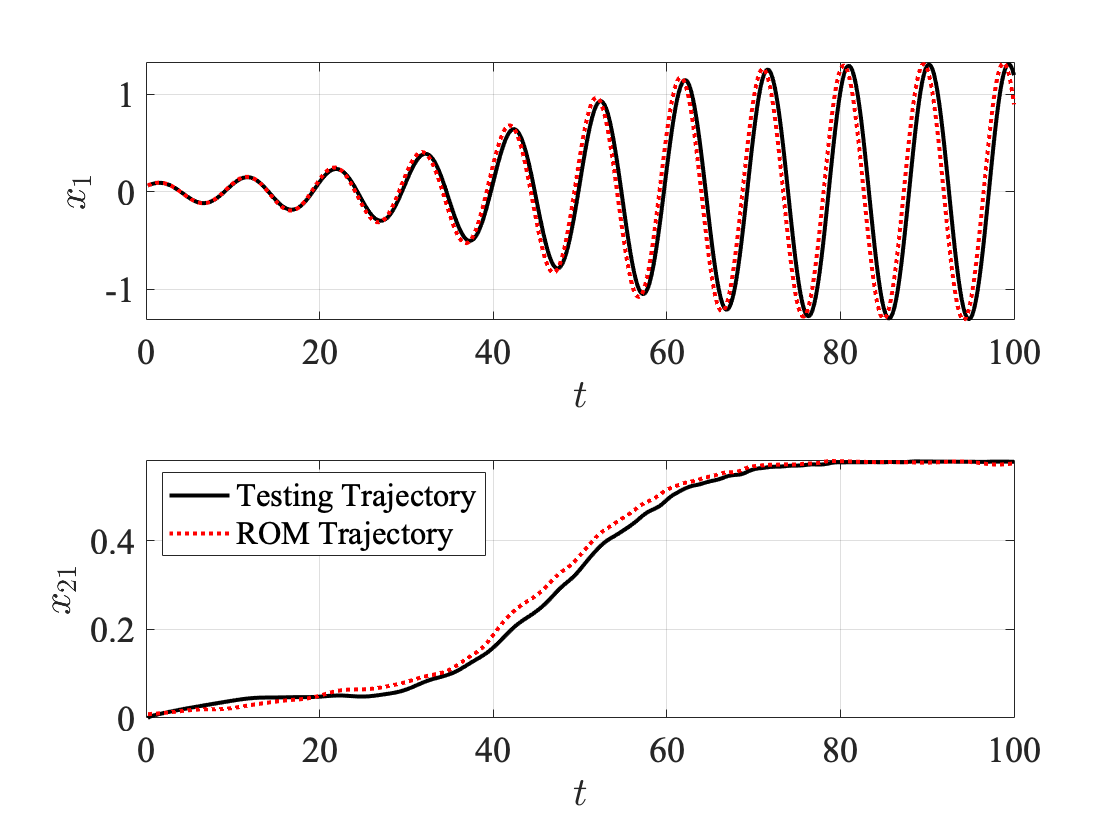


figure(42); clf; 
subplot(211); hold on; grid on; box on;
plot(t_i,x_i(1,:),'k','Linewidth',2,'DisplayName','Testing Trajectory')
plot(t_i,x_sim(1,:),'r:','Linewidth',2,'DisplayName','ROM Trajectory')
xlabel('$t$','Interpreter','latex')
ylabel('$x_{1}$','Interpreter','latex')
set(gca,'fontname','times')
set(gca,'fontsize',18)
subplot(212); hold on; grid on; box on;
plot(t_i,x_i(21,:),'k','Linewidth',2,'DisplayName','Testing Trajectory')
plot(t_i,x_sim(21,:),'r:','Linewidth',2,'DisplayName','ROM Trajectory')
xlabel('$t$','Interpreter','latex')
ylabel(['$x_{21}$'],'Interpreter','latex')
set(gca,'fontname','times')
set(gca,'fontsize',18)
legend('location','NW')

RRMSE = mean(sqrt(sum( (x_i-x_sim).^2 )))/max(sqrt(sum(x_i.^2)))*100 %

RRMSE =        18.963


Plotting figure with the polar normal form equations ... Done. 


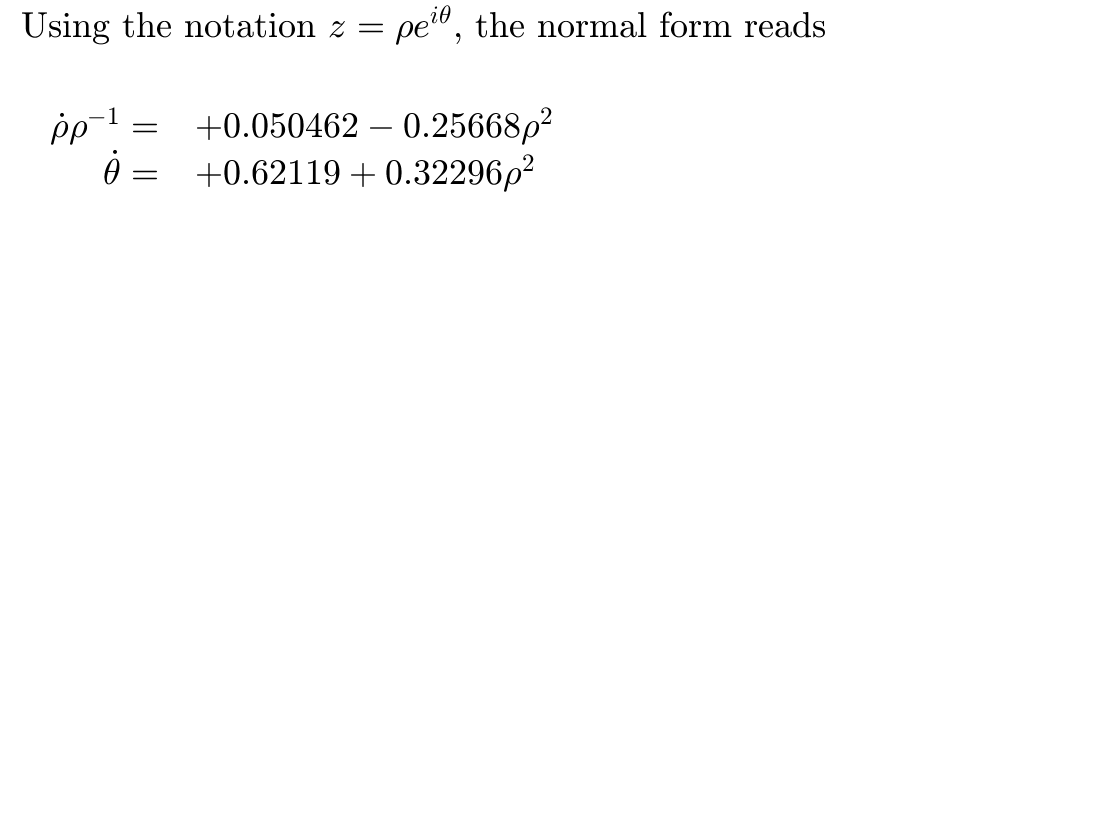


[damp,freq,str_eqn] = polarnormalform(N_info.coeff,N_info.exponents,N_info.phi);

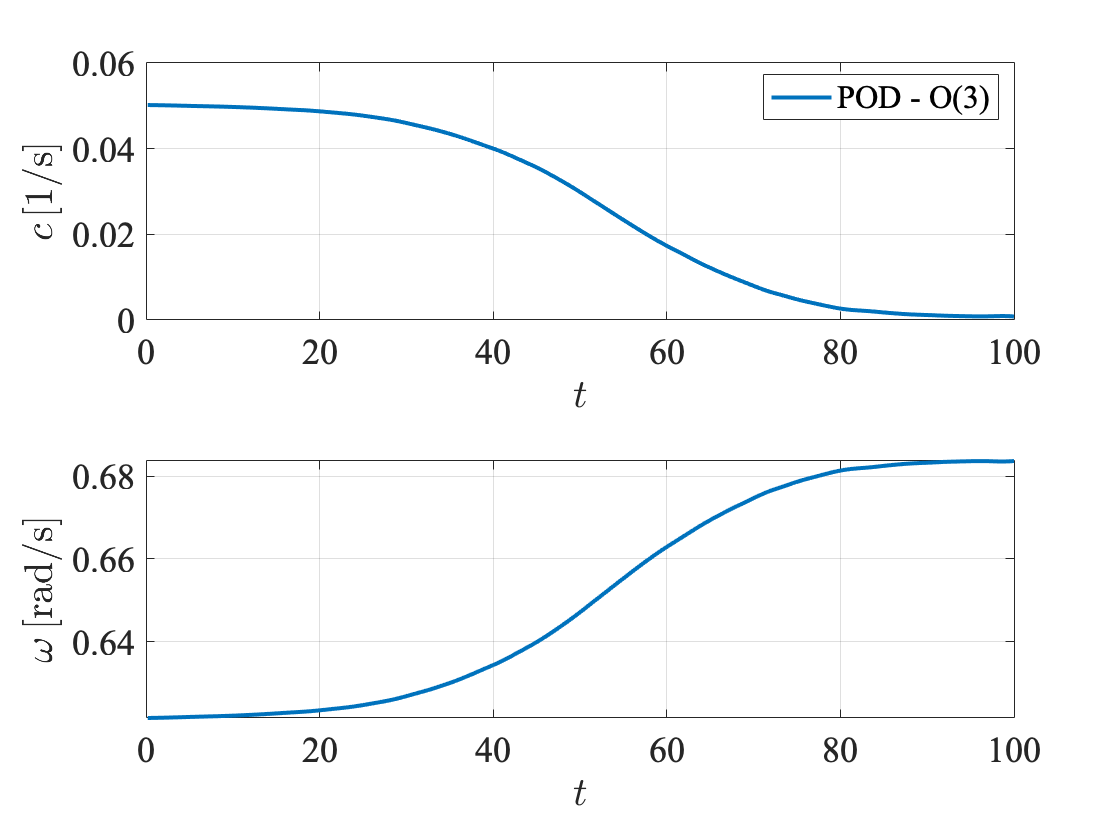

figure
subplot(211); hold on; grid on; box on;
plot(t_i,damp(abs(z_i(1,:))),'Linewidth',2,'DisplayName',['POD - O(' num2str(NPolyOrd) ')'])
xlabel('$t$','Interpreter','latex')
ylabel('$c \, [$1/s$]$','Interpreter','latex')
set(gca,'fontname','times')
set(gca,'fontsize',18)
xlim([0 100])
legend
subplot(212); hold on; grid on; box on;
plot(t_i,freq(abs(z_i(1,:))),'Linewidth',2,'DisplayName',['POD - O(' num2str(NPolyOrd) ')'])
xlabel('$t$','Interpreter','latex')
ylabel('$\omega \, [$rad/s$]$','Interpreter','latex')
set(gca,'fontname','times')
set(gca,'fontsize',18)
xlim([0 100])

drawnow;